for ii = [10000 7500 5000 2500 1000 0]
load_system("CSTR_Bioreactor_2023_FeedForward.slx");

% -----
set_param("CSTR_Bioreactor_2023_FeedForward/mv_dilution_step", "After", "-0.025");
set_param("CSTR_Bioreactor_2023_FeedForward/mv_coolingtemp_step", "After", "0");
% -----

set_param("CSTR_Bioreactor_2023_FeedForward/toggle_glucose", "Value", num2str(1));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_biotemp", "Value", num2str(1));

set_param("CSTR_Bioreactor_2023_FeedForward/PID_glucose", "P", num2str(4));
set_param("CSTR_Bioreactor_2023_FeedForward/toggle_feedforward", "Value", num2str(1));
set_param("CSTR_Bioreactor_2023_FeedForward/feedforward_gain", "Gain", num2str(ii));


simulate = sim("CSTR_Bioreactor_2023_FeedForward");
[pv_ethanolconc, pv_biotemp, pv_ethanolconc_derivative, pv_biotemp_derivative] = extract_ts(simulate, 450, 1000);
plot(pv_ethanolconc)
hold on
end

% xline(500,"--","Disturbance")
yline(40,"--","Set point")
legend("Gain 10000","Gain 7500","Gain 5000","Gain 2500","Gain 1000","No Feedforward")

% xline(500,"--b")
% yline(40,"--")


xlim([450,1000])
% ylim([25,50])


title("")
ylabel("Ethanol concentration / gL^{-1}")
xlabel("Time / h")

Plot();

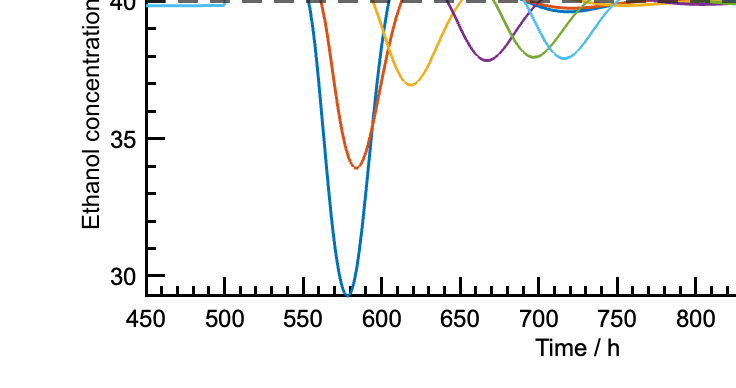

hold off
exportgraphics(gcf,"figures/ManualFeedbackManualFeedforward_WithDisturbance_Dilution_Ethanol.pdf")